clear; clc;
cd ~/git/hardDiskControl/discreteTimeControl/
load ../data/sysDT.mat
load ../data/Gz.mat
load ../data/plantTF.mat

Kd = [sysDT.B sysDT.A*sysDT.B sysDT.A^2*sysDT.B sysDT.A^3*sysDT.B]

Kd = 1.0e-03 *

   -0.5241    0.2292    0.3130    0.0956
    0.0008    0.0005   -0.0000   -0.0002
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000


rank(Kd)

ans = 4

discrete system is controllable, which means all poles can be arbitrarily placed.

load ../data/sysCT.mat
Kd = [sysCT.B sysCT.A*sysCT.B sysCT.A^2*sysCT.B sysCT.A^3*sysCT.B]

Kd =            1        -200     -960000   392000000
           0           1        -200     -960000
           0           0           1        -200
           0           0           0           1


rank(Kd)

ans = 4

we will design in CT because the A matrix is much easier to work, and it is easier to place the poles to be conform the controller requirements, like overshoot.

In a 2d system, there can be only one complex conjugate pole pair. Hence, there we can perfectly comute the behaviour of the system. However, with a 4d system this becomes harder. What we can however do is place our non-dominant pole pair well withing the pole placement restrictions for the desired behaviour and we should be fine. THe dominat pole pair can than be placed a little less agressively compared to where we ould place the 2d system.

For intuition's sake we will do this in continuous time and then compute the corresponsing z-domain locations afterwards. Because the discretised system's dynamics is also subject to the sampling time we might have to reduce optimality a little bit for the sake of stability.

maxDamp = -log(0.05)/sqrt(pi^2+log(0.05)^2);
degMaxDamp = rad2deg(acos(maxDamp));

mag1 = 100;
phase1 = degMaxDamp;
pole1 = -mag1*cosd(phase1)+mag1*sind(phase1)*1i;
pole1c = -mag1*cosd(phase1)-mag1*sind(phase1)*1i;

mag2 = 1000;
phase2 =degMaxDamp/5;
pole2 = -mag2*cosd(phase2)+mag2*sind(phase2)*1i;
pole2c = -mag2*cosd(phase2)-mag2*sind(phase2)*1i;

poles = [pole1; pole1c; pole2 ;pole2c];

mag1 = 100;
phase1 = degMaxDamp;
pole1FF = -mag1*cosd(phase1)+mag1*sind(phase1)*1i;
pole1cFF = -mag1*cosd(phase1)-mag1*sind(phase1)*1i;3.4E-9

ans = 3.4000e-09

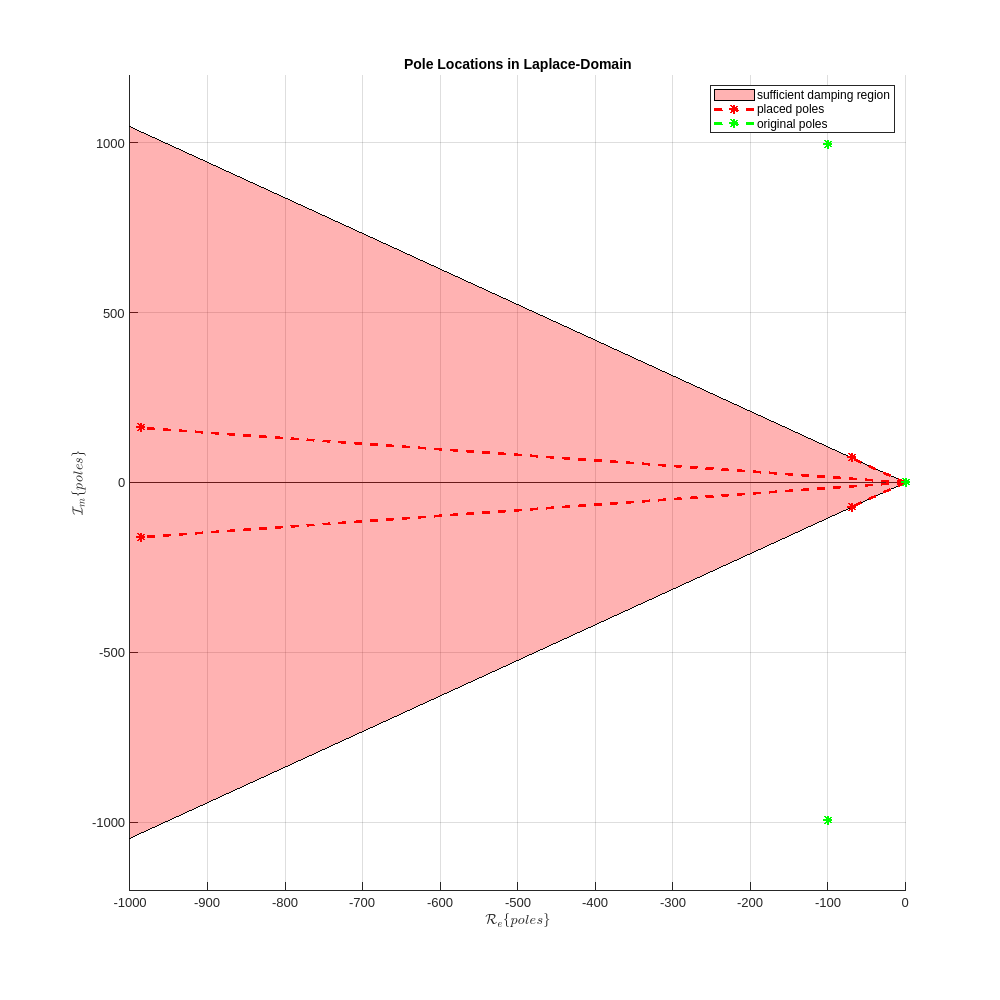


mag2 = 1000;
phase2 =degMaxDamp/5;
pole2FF = -mag2*cosd(phase2)+mag2*sind(phase2)*1i;
pole2cFF = -mag2*cosd(phase2)-mag2*sind(phase2)*1i;

polesFF = [pole1FF; pole1cFF; pole2FF; pole2cFF];

polesMax = poles(3);
maxMag = max(abs(poles));

figure('Position',[0 0 1000 1000]);clf;hold on;
grid on;
l1 = area([-2*maxMag*cosd(degMaxDamp) -2*maxMag*cosd(degMaxDamp) 0],[0 2*maxMag*sind(degMaxDamp) 0],'FaceAlpha',0.3,'FaceColor','r');
area([-2*maxMag*cosd(degMaxDamp) -2*maxMag*cosd(degMaxDamp) 0],[0 -2*maxMag*sind(degMaxDamp) 0],'FaceAlpha',0.3,'FaceColor','r')
l2 = plot([0 real(pole1)],[0 imag(pole1)],'--*','LineWidth',2, 'Color','r');
plot([0 real(pole1c)],[0 imag(pole1c)],'--*','LineWidth',2, 'Color','r')
plot([0 real(pole2)],[0 imag(pole2)],'--*','LineWidth',2, 'Color','r')
plot([0 real(pole2c)],[0 imag(pole2c)],'--*','LineWidth',2, 'Color','r')
% axis([-abs(1.2*real(polesMax)) abs(1.2*real(polesMax)) -abs(1.2*imag(polesMax)) abs(1.2*imag(polesMax))])
axis([-maxMag 0 -maxMag*1.2 maxMag*1.2])
originalPoles = pole(sysCT);
l3 = plot(real(originalPoles(1)),imag(1i),'--*','LineWidth',2, 'Color','g');
plot(real(originalPoles(1)),imag(-1i),'--*','LineWidth',2, 'Color','g')
plot(real(originalPoles(3)),imag(originalPoles(3)),'--*','LineWidth',2, 'Color','g')
plot(real(originalPoles(4)),imag(originalPoles(4)),'--*','LineWidth',2, 'Color','g')
title('Pole Locations in Laplace-Domain')
xlabel('$\mathcal{R}_e\{poles\}$','Interpreter','latex')
ylabel('$\mathcal{I}_m\{poles\}$','Interpreter','latex')
legend([l1, l2, l3],'sufficient damping region', 'placed poles', 'original poles','Location','northeast')

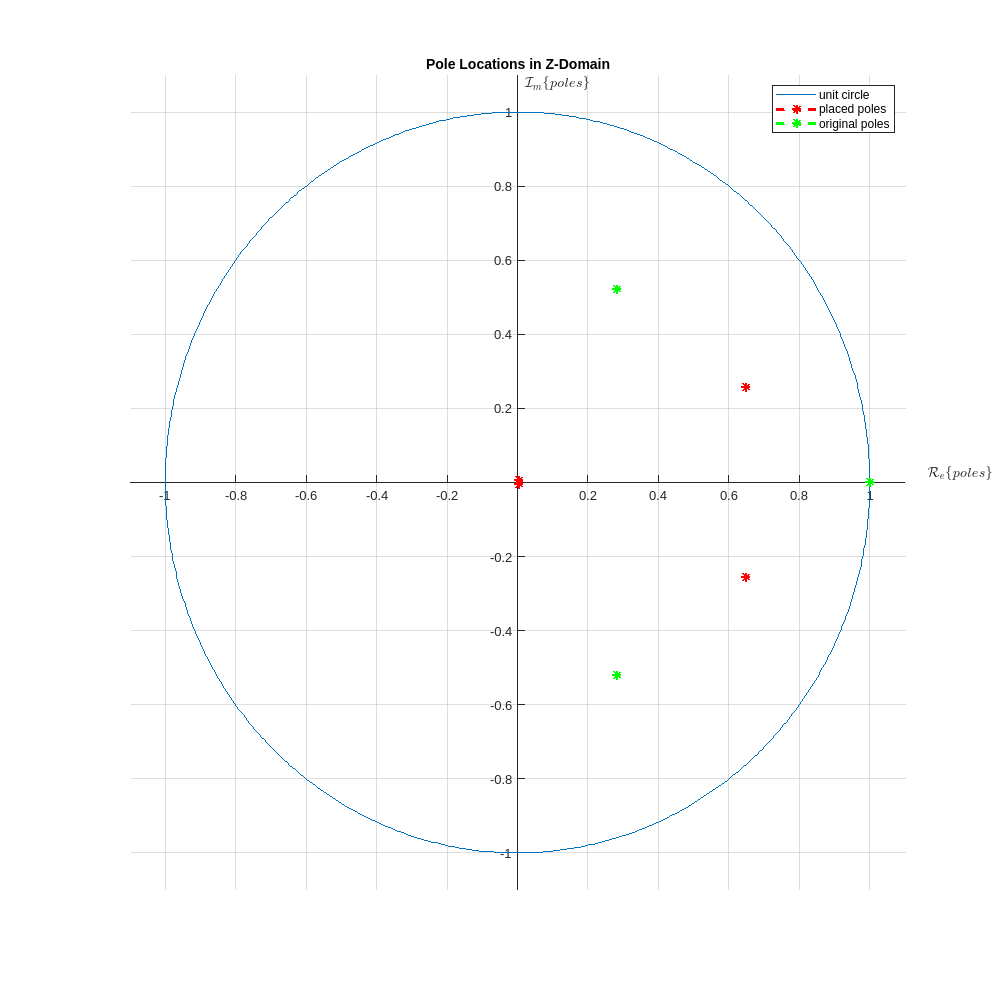

p = poles;
% p(3) = 0;
% p(4) = -10;
[F, prec] = place(sysCT.A,sysCT.B,p);
Acl = sysCT.A-sysCT.B*F;
sysCTcl = ss(Acl,sysCT.B,sysCT.C,sysCT.D);
sysCTclFF = sysCTcl;
sysCTclFF.B = dcgain(sysCTclFF)^-1 * sysCTclFF.B;
riseTime = 0.052333; %seconds
Ts = riseTime/10;
zPoles = exp(poles.*Ts);
zPolesFF = exp(polesFF.*Ts);
zOriginalPoles = exp(originalPoles.*Ts);

figure('Position',[0,0,1000,1000]);clf;hold on;

l1 = circle(0,0,1);
for i=1:4
    l2 = plot(real(zPoles(i)),imag(zPoles(i)),'--*','LineWidth',2,'Color','r');
    l3 = plot(real(zOriginalPoles(i)),imag(zOriginalPoles(i)),'--*','LineWidth',2,'Color','g');
end
axis([-1.1 1.1 -1.1 1.1]);
grid on;
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
legend([l1,l2,l3],'unit circle','placed poles','original poles');
title('Pole Locations in Z-Domain')
xlabel('$\mathcal{R}_e\{poles\}$','Interpreter','latex','Position',[1.35,0])
ylabel('$\mathcal{I}_m\{poles\}$','Interpreter','latex','Position',[0.02,1.1])

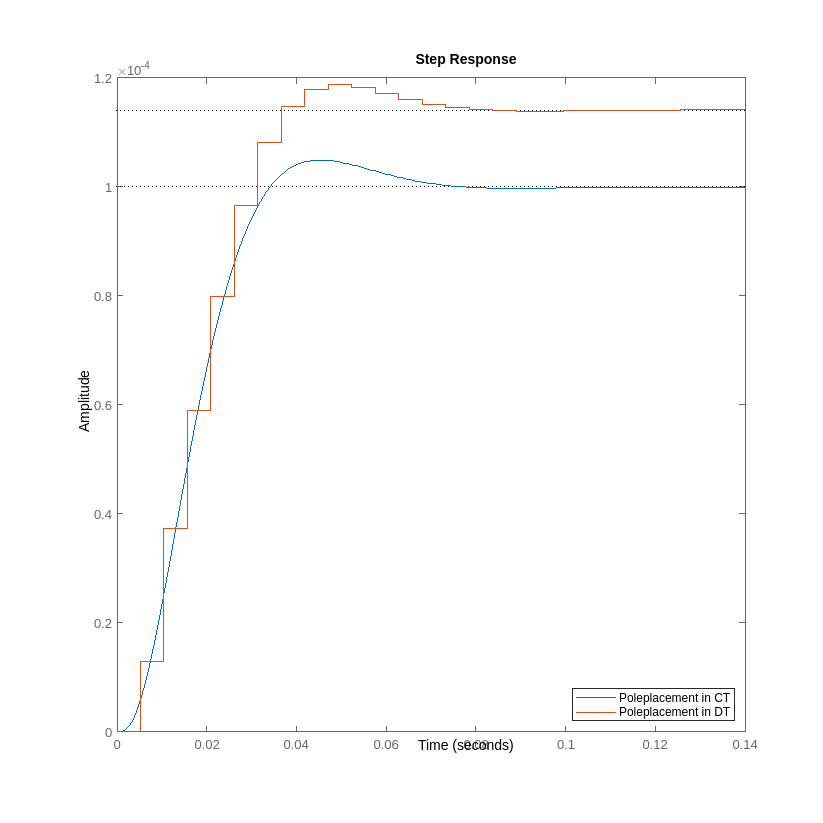

[F,prec] = place(sysDT.A,sysDT.B,zPoles);
sysDTcl = ss(sysDT.A-sysDT.B*F,sysDT.B,sysDT.C,sysDT.D,Ts);

sysDTclFF = sysDTcl;
dcGain = dcgain(sysDTclFF);
sysDTclFF.B = sysDTclFF.B*dcgain(sysDTclFF)^-1;

figure('Position',[0,0,1000,1000]);clf;hold on;
step(sysCTcl)
step(sysDTcl)
legend('Poleplacement in CT','Poleplacement in DT','Location','southeast');

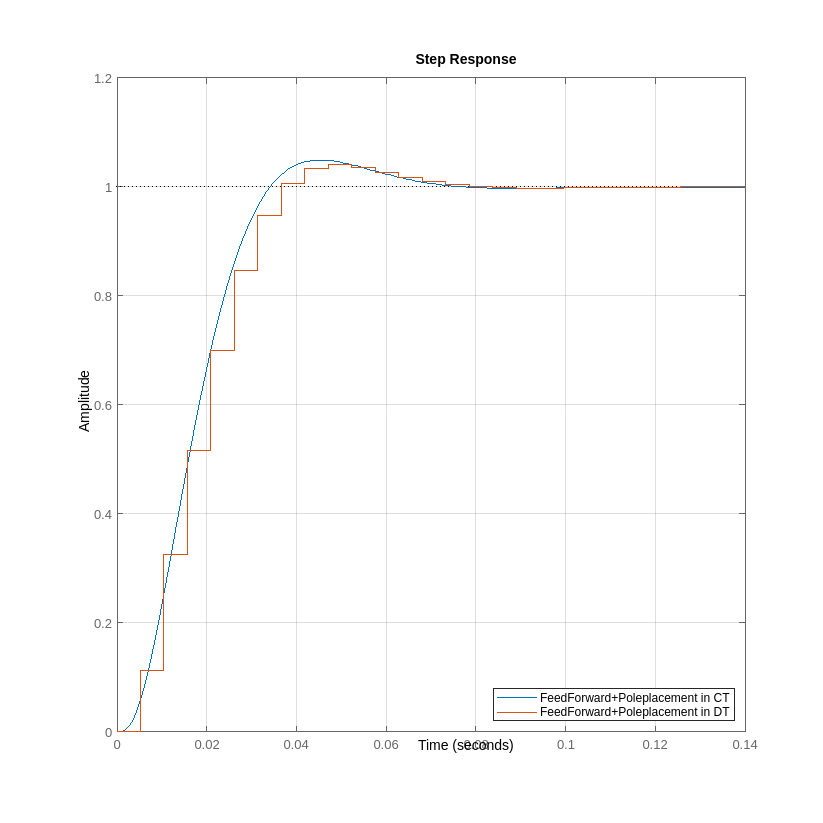


figure('Position',[0,0,1000,1000]);clf;hold on;
step(sysCTclFF)
step(sysDTclFF); grid on;
legend('FeedForward+Poleplacement in CT','FeedForward+Poleplacement in DT','Location','southeast');

stepinfo(step(sysDTclFF))

ans = struct with fields:
         RiseTime: 4.6439
    TransientTime: 12.7473
     SettlingTime: 12.7473
      SettlingMin: 0.9474
      SettlingMax: 1.0404
        Overshoot: 4.0444
       Undershoot: 0
             Peak: 1.0404
         PeakTime: 10


function plot1 = circle(x,y,r)
%x and y are the coordinates of the center of the circle
%r is the radius of the circle
%0.01 is the angle step, bigger values will draw the circle faster but
%you might notice imperfections (not very smooth)
ang=0:0.01:2*pi; 
xp=r*cos(ang);
yp=r*sin(ang);
plot1 = plot(x+xp,y+yp);
end